# Practica 2 - Métodos iterativos de resolución de sistemas lineales, $A x = b$

## Problema 4

Consideremos el sistema lineal $Ax = b$, de tamaño $n = 500$, donde $A = (a_{ij})$ es una matriz simétrica tal que

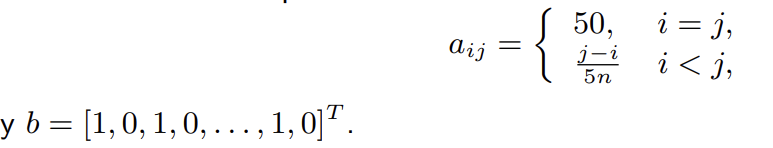

### (a) Utiliza como criterio de parada la norma euclídea del residuo, una tolerancia de $10^{-10}$ y como aproximación inicial un vector de ceros para aproximar la solución del sistema por el método de Jacobi. Proporciona el número de iterados, la norma y el valor máximo del último residuo y el tiempo de ejecución. Representa, en escala semilogarítmica, todos los residuos calculados. ¿Porqué el método es convergente?

Definimos primero el sistema descrito en la pregunta, utilizando para ello la función Practica2_4_matriz()

n = 500;
[A, b] = Practica2_4_matriz(n);

Luego, creamos el script Practica2_Jacobi(), donde desarrollamos el método de Jacobi con las prestaciones dadas en la pregunta. Ejecutamos el método:

tic;
[sol, incr, iter, resid, ACOC] = Practica2_Jacobi(A, b, zeros(n, 1), 1e-10, 1000);
execTime = toc;

De ahi obtenemos el número de iterados, la norma y el valor máximo del ultimo residuo y el tiempo de ejecucion. 

iter

iter = 61

%Norma del ultimo residuo
norm(resid)

ans = 9.3672e-11

%Maximo del ultimo residuo
max(resid)

ans = -3.2718e-12

execTime

execTime = 0.0183

Representamos los residuos (sus normas) en escala logaritmica:

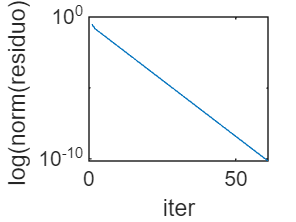

semilogy(incr)
xlabel('iter')
ylabel('log(norm(residuo))')

Representamos tambien el ACOC

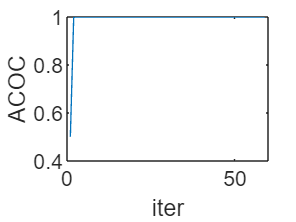

plot(ACOC)
xlabel('iter')
ylabel('ACOC')

Vemos que converge linealmente.

### (b) ¿Es la matriz A definida positiva? En caso afirmativo, aproxima la solución del sistema por el método del gradiente, con los mismos datos del apartado anterior. Proporciona todo lo que se pide en el apartado anterior así como la representación del ACOC. Escribe el programa que has elaborado para afirmar si A es una matriz definida positiva o no.

Veamos si A es definida positiva utilizando el programa DefinidaPositiva()

DefinidaPositiva(A)

DEFINIDA POSITIVA.


ans = 1

Si que lo es. Utilicemos el método del gradiente.

tic;
[sol, incr, iter, resid, ACOC] = Practica2_Gradiente(A, b, zeros(n, 1), 1e-10, 100);
execTime = toc;
execTime

execTime = 0.0094

iter

iter = 29

norm(resid)

ans = 8.7317e-11

max(resid)

ans = 7.8019e-12

Representemos las normas de los residuos asi como el ACOC

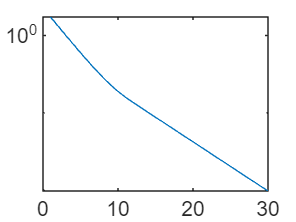

semilogy(incr)

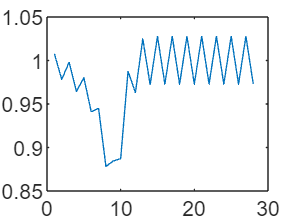

plot(ACOC)

Vemos que el ACOC no se estabiliza. No nos da informacion sobre su convergencia.

### (c) Aproxima la solución del sistema por el método del gradiente conjugado, con los mismos datos del apartado (a). Proporciona todo lo que se pide en el apartado (a) así como la representación del ACOC.

Escribimos una variación del programa del gradiente conjugado y repetimos el mismo proceso que en (a) y en (b)

tic;
[sol, incr, iter, resid, ACOC] = Practica2_GradienteConjugado(A, b, zeros(n, 1), 1e-10, 100);
execTime = toc;
execTime

execTime = 0.0047

iter

iter = 7

norm(resid)

ans = 4.5866e-13

max(resid)

ans = 1.0619e-13

Representamos las normas de los residuos y el ACOC

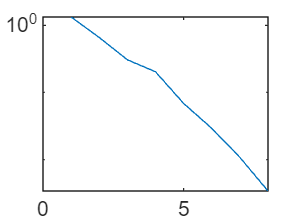

semilogy(incr)

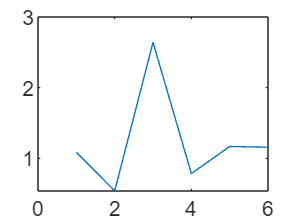

plot(ACOC)

Vemos que el ACOC parece ir a converger a 1, pero por las pocas iteraciones que hacen no se puede saber